## Newton's method for inverse kinematics

### Parameters

% Initial guess for joint angles
theta1 = pi/2;
theta2 = pi/2;
theta3 = pi/2;

% Desired end-effector position
x_desired = 2;
y_desired = 1;
phi_desired = 0;

% Gradient descent parameters
max_iterations = 1000;  % Maximum number of iterations
tolerance = 1e-6;       % Tolerance for convergence

### Plotting setup

% Plotting setup for x-coordinate
fig_x = figure('WindowStyle', 'normal');
xlabel('Iteration');
ylabel('X');
title('End-Effector X Movement');
hold on;

% Plotting setup for y-coordinate
fig_y = figure('WindowStyle', 'normal');
xlabel('Iteration');
ylabel('Y');
title('End-Effector Y Movement');
hold on;

% Plotting setup for y-coordinate
fig_phi = figure('WindowStyle', 'normal');
xlabel('Iteration');
ylabel('PHI');
title('End-Effector PHI Movement');
hold on;

% Initialize error vector
errors = zeros(1, max_iterations);

### Gradient method algorithm

% Initial end-effector position
[x, y, phi] = forward_kinematics(theta1, theta2, theta3);
figure(fig_x);
plot(0, x, 'bo', 'MarkerSize', 10, 'DisplayName', 'Initial X');
figure(fig_y);
plot(0, y, 'bo', 'MarkerSize', 10, 'DisplayName', 'Initial Y');
figure(fig_phi);
plot(0, phi, 'bo', 'MarkerSize', 10, 'DisplayName', 'Initial PHI');


% Gradient descent optimization
for iter = 1:max_iterations
    % Calculate the error
    [x, y, phi] = forward_kinematics(theta1, theta2, theta3);
    error = error_function(x_desired, y_desired, phi_desired, theta1, theta2, theta3);
    errors(iter) = error;

    % Display current iteration and error
    fprintf('Iteration %d \n', iter);
    fprintf('\tIK: [theta1: %.4f, theta2: %.4f, theta3: %.4f]\n', theta1, theta2, theta3);
    fprintf('\tDK: [x: %.4f, y: %.4f, phi: %.4f]\n', x, y, phi);
    fprintf('\tError: %.8f\n', error);
    
    % Check for convergence
    if error < tolerance
        disp('Converged!');
        break;
    end


    % Plot the movement of the end-effector for x-coordinate
    figure(fig_x);
    plot(iter, x, 'ko-', 'LineWidth', 1, 'MarkerSize', 4, 'DisplayName', ['Iteration ', num2str(iter)]);
    % Plot the movement of the end-effector for y-coordinate
    figure(fig_y);
    plot(iter, y, 'ko-', 'LineWidth', 1, 'MarkerSize', 4, 'DisplayName', ['Iteration ', num2str(iter)]);
    % Plot the movement of the end-effector for phi-coordinate
    figure(fig_phi);
    plot(iter, phi, 'ko-', 'LineWidth', 1, 'MarkerSize', 4, 'DisplayName', ['Iteration ', num2str(iter)]);


    % Calculate the Jacobian matrix
    J = jacobian(theta1, theta2, theta3);
    
    % Calculate the gradient of the error
    grad_error = J' * [(x_desired - x); (y_desired - y); (phi_desired - phi)];
    
    % Calculate the Hessian matrix
    H = J' * J;

    % Update the joint angles using Newton's method
    delta_theta = H \ grad_error;
    theta1 = theta1 + delta_theta(1);
    theta2 = theta2 + delta_theta(2);
    theta3 = theta3 + delta_theta(3);
end

Iteration 1 


	IK: [theta1: 1.5708, theta2: 1.5708, theta3: 1.5708]


	DK: [x: -1.0000, y: 0.0000, phi: 4.7124]


	Error: 5.67508677


Iteration 2 


	IK: [theta1: -6.1416, theta2: 8.2832, theta3: -2.1416]


	DK: [x: 1.4497, y: 0.9826, phi: 0.0000]


	Error: 0.55058511


Iteration 3 


	IK: [theta1: -6.4525, theta2: 7.9922, theta3: -1.5397]


	DK: [x: 2.0168, y: 0.8310, phi: -0.0000]


	Error: 0.16979269


Iteration 4 


	IK: [theta1: -6.2825, theta2: 7.8676, theta3: -1.5852]


	DK: [x: 1.9856, y: 1.0006, phi: -0.0000]


	Error: 0.01437285


Iteration 5 


	IK: [theta1: -6.2833, theta2: 7.8541, theta3: -1.5708]


	DK: [x: 2.0000, y: 0.9999, phi: -0.0000]


	Error: 0.00010312


Iteration 6 


	IK: [theta1: -6.2832, theta2: 7.8540, theta3: -1.5708]


	DK: [x: 2.0000, y: 1.0000, phi: 0.0000]


	Error: 0.00000001


Converged!




% Display final joint angles
disp('Final Joint Angles:');

Final Joint Angles:


disp(['Theta1: ', num2str(theta1)]);

Theta1: -6.2832


disp(['Theta2: ', num2str(theta2)]);

Theta2: 7.854


disp(['Theta3: ', num2str(theta3)]);

Theta3: -1.5708


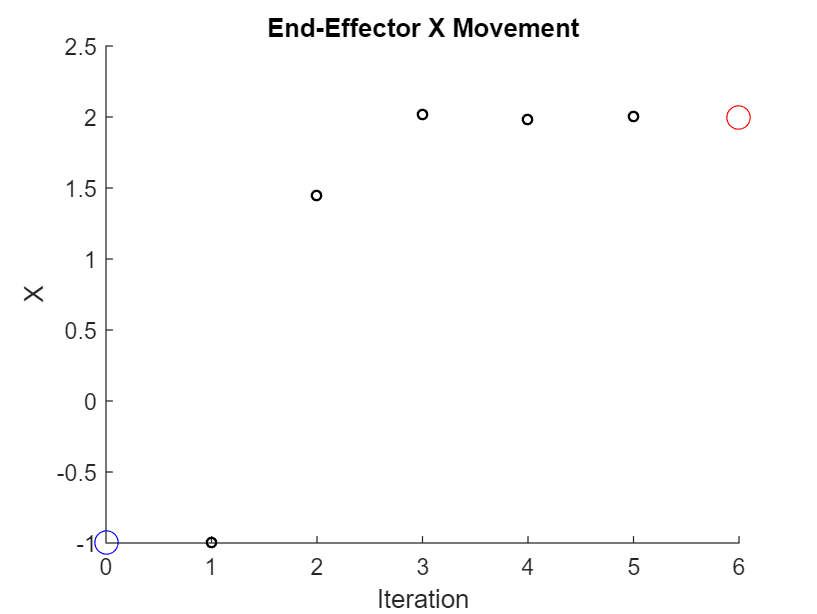



% Final end-effector position
figure(fig_x);
plot(iter, x, 'ro', 'MarkerSize', 10, 'DisplayName', 'Final X');
%legend('show');
hold off;

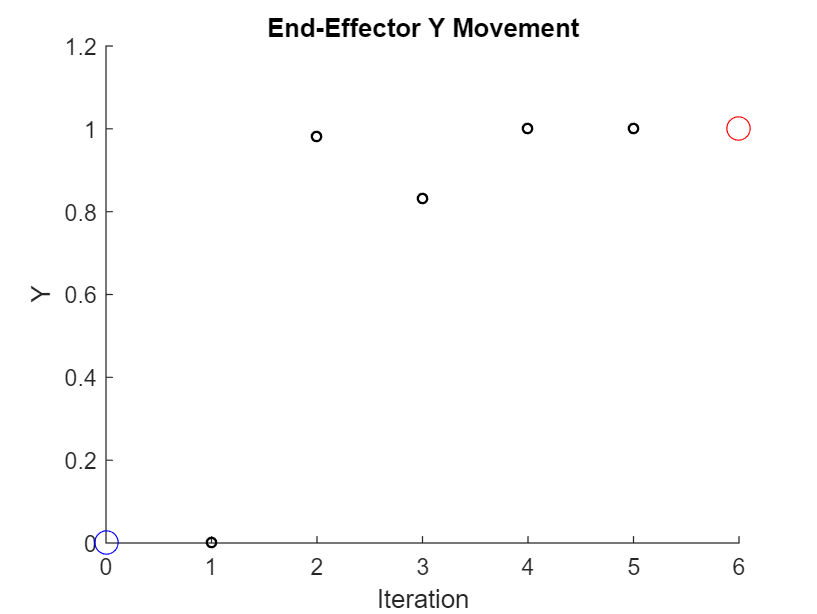


figure(fig_y);
plot(iter, y, 'ro', 'MarkerSize', 10, 'DisplayName', 'Final Y');
%legend('show');
hold off;

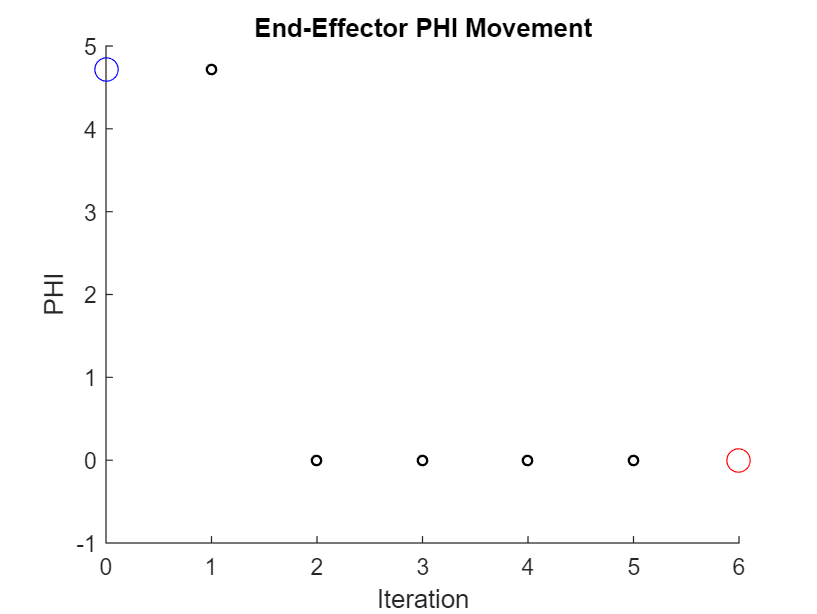


figure(fig_phi);
plot(iter, phi, 'ro', 'MarkerSize', 10, 'DisplayName', 'Final PHI');
%legend('show');
hold off;

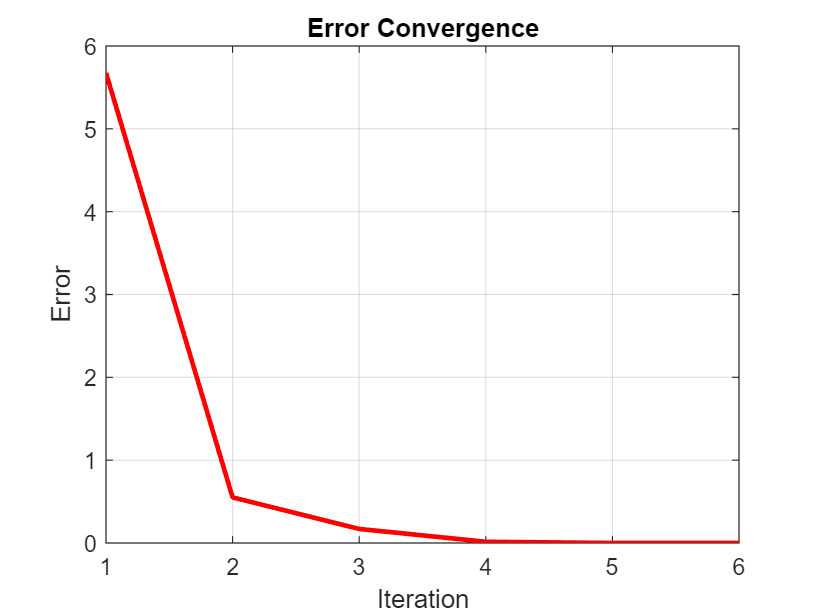


% Plot the error
figure;
plot(1:iter, errors(1:iter), 'r-', 'LineWidth', 2);
xlabel('Iteration');
ylabel('Error');
title('Error Convergence');
grid on;